# **ACM 11 Homework 1 (Spring 2021)**

## **Due Friday, April 1, 11:59pm Pacific Time, by upload to Canvas.**

This assignment is worth 100 points. The points in this file add up to 50 points - if your code completes the task correctly then you will receive the full 50 points for credit. An additional 10 points are allocated to readable code. A further 10 points are allocated to efficient code (unless explicitly instructed to write inefficient code). The final 30 points for the written answers to the questions in the code being clear, correct, and in complete sentences.

### Problem 1 (5 points)

Use the `disp` command to write a "Hello World" program in the following block.

disp("Hello World");

Hello World


### **Problem 2 (Fibonacci sequence, 10 points)**

The classical Fibonacci sequence of integers is defined via the following recursive relation:


$$F_{m+2} = F_{m+1}+F_{m} \  (m \geq 1), \ F_{1}=F_{2}=1$$


Write a script that uses a for loop to compute the first $$n = 20$$ terms $$\{F_{m}\}_{m=1}^{n}$$ in the Fibonacci sequence in the following block. Use the `zeros` command to pre-allocate a 20-by-1 array for all the terms of the sequence. Suppress the output within your for loop but display all computed elements at the end.

allTerms = zeros(20,1); % preallocate 20x1 array
allTerms(1) = 1; % set first two terms as 1
allTerms(2) = 1;

for n = 3:20 % for remaining n in 20
    allTerms(n) = allTerms(n-1) + allTerms(n-2); % find curr Fib term
end

disp('Fibonacci Terms');

Fibonacci Terms


disp(allTerms);

           1
           1
           2
           3
           5
           8
          13
          21
          34
          55
          89
         144
         233
         377
         610
         987
        1597
        2584
        4181
        6765



As a check of your work, the 20th Fibonacci number is 6765. Compare the 20th element of your Fibonacci array by subtracting it from the true answer -- the error should be 0:

error = 6765 - allTerms(20);

disp("Error");

Error


disp(error);

     0



### **Problem 3 (Pre-allocation, 15 points)**

Here we will use a toy example to illustrate how preallocation can help optimize your MATLAB code. In your later work, you should always try preallocating the maximum amount of space required for an array at first instead of continuously resizing the array.

Consider a sequence $$\{x_{k}\}_{k=1}^{\infty}$$ defined as follows:


$$$x_{k+1} = \frac{1}{2}(x_{k}^2-x_{k}+2), \ x_{1} = \frac{3}{2}$$$


We want to compute the first $$10^6$$ terms in this sequence and store them in a row vector.

**(5 points) **Initialize the final output as a scalar and append a new term to it in each round of the loop. Record the running time (Hint: try using "tic" and "toc" ) Please write your code in the following block:

unallT = tic;

output1 = 3/2; % initialize as scalar

for k = 2:100000 % for remaining k in 10^6
    x = 1/2 * (output1(k-1)^2 - output1(k-1) + 2); % find curr x
    output1 = [output1, x]; % append x to output
end

unallT = toc(unallT);
disp('Run Time for Unallocated Code');

Run Time for Unallocated Code


disp(unallT);

    1.3455



**(5 points) **Initialize the final output as an array with the desired size and update one term in the array in each round of the loop. Please write your code in the following block:

allT = tic;

output2 = zeros(1000000,1); % preallocate array of 10^6x1
output2(1) = 3/2; % set first value

for k = 2:1000000 % for remaining k in 10^6
    output2(k) = 1/2 * (output2(k-1)^2 - output2(k-1) + 2); % set curr k
end

allT = toc(allT);
disp('Run Time for Allocated Code');

Run Time for Allocated Code


disp(allT);

    0.0203



**(5 points) **Compare the two running times you recorded above. Briefly discuss what you observed. (Please write your discussion in the string in the following block.)

disp("The run time for when we do not pre-allocate a set array size is much larger than that of when we do pre-allocate.  " + ...
    "This is clearly observable with run times of 1.3173 and 0.0206, respectively." + ...
    "This correlates with expectations, where we 'waste' computational resources resizing our array at each step.")

The run time for when we do not pre-allocate a set array size is much larger than that of when we do pre-allocate.  This is clearly observable with run times of 1.3173 and 0.0206, respectively.This correlates with expectations, where we 'waste' computational resources resizing our array at each step.


### **Problem 4 (Plotting a line, 10 points)**

We want to plot the line $y=m\;x+b$ for different values of $m$. In the following block, fix $b=2\ldotp 2$ and loop through 6 values of $m$ between 1 and 3, and plot y vs. x on the same axis for x in [0,1] in different colors using the hold command. Label your axes and give the plot a title. Include an appropriate legend.

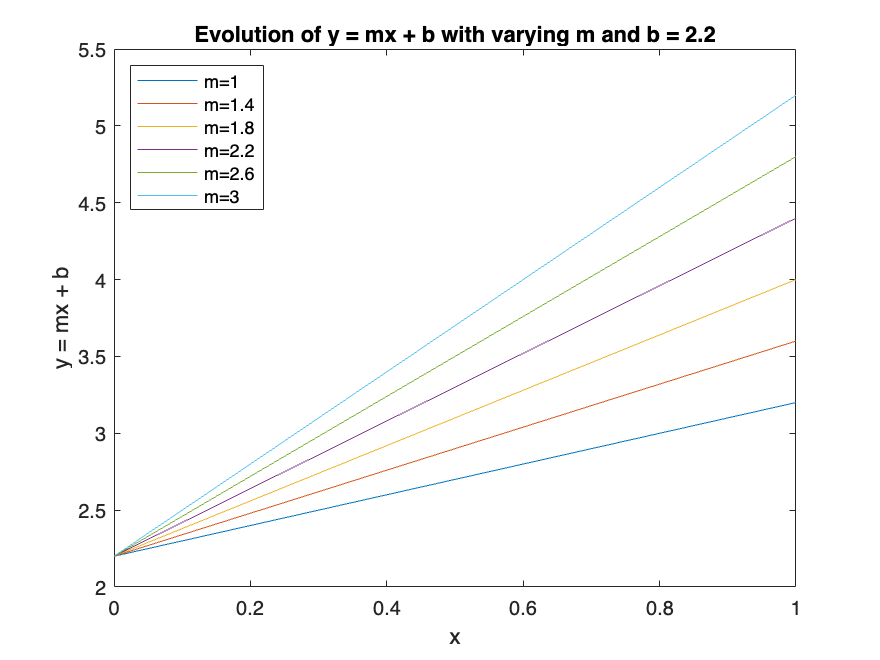

% problem parameters
b = 2.2;
n = 1;
M = linspace(1,3,6); % make uniform array of size 6 on [1,3]
X = linspace(0,1); % make uniform array on [0,1]

figure(1); clf
for m = M % for each m in M
    plot(X, m*X + b); % plot y = mx + b
    hold on
end
hold off
xlabel('x');
ylabel('y = mx + b');
legend({'m=1','m=1.4','m=1.8','m=2.2','m=2.6','m=3'},'Location','northwest');
title('Evolution of y = mx + b with varying m and b = 2.2');

### **Problem 5 (Plotting a multivariate function, 10 points)**

We want to plot the function $z=m{\;}_1 x+m_2 y^2$ for (x,y) in [0,1]x[-0.5,0.5] (i.e. on the unit square). We will use $m_1 =2$ and $m_2 =3$. We will do this several ways. 

**(3 points) **First, define an array of x-values from 0 to 1  with 10 points, and an array of y-values from -0.5 to 0.5 with 15 points. Pre-allocate an 15x10 array for z, and **loop** through every combination of x- and y-values to fill in the z array. Use the tic/toc commands to time how long this takes. Then use the surf command to plot z vs. x and y. Label your axes. 

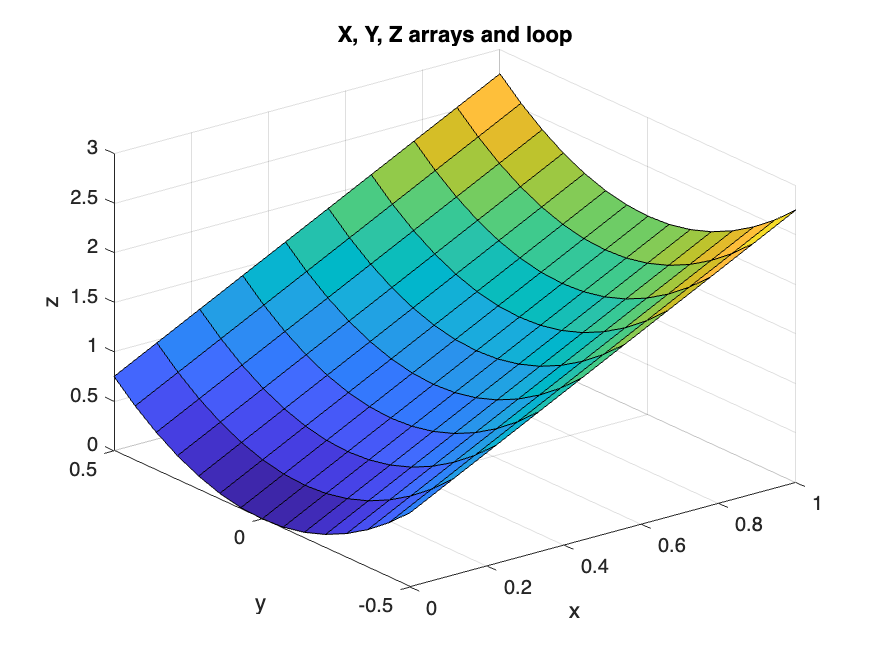

m1 = 2;
m2 = 3;
arrayT = tic;
X = linspace(0,1,10); % make uniform array of size 10 on [0,1]
Y = linspace(-0.5,0.5,15); % make uniform array of size 15 on [-0.5,0.5]
Z = zeros(15,10); % preallocate array of size 15x10

for i = 1:10 % for each index in X
    for j = 1:15 % for each index in Y
        Z(j,i) = m1*X(i) + m2*Y(j)^2; % calculate z
    end
end

arrayT = toc(arrayT);
figure(2); clf
surf(X,Y,Z);
xlabel('x');
ylabel('y');
zlabel('z');
title('X, Y, Z arrays and loop')

disp("Run Time for X, Y, Z arrays and loop");

Run Time for X, Y, Z arrays and loop


disp(arrayT);

    0.0061



**(4 points) **Now compute the values of the z-array for the above function above in one line, without using a loop. Use the tic/toc commands to time how long this takes. Use the surf command to plot z vs. x and y again. It should look identical to your above plot (otherwise you need to check your code!).

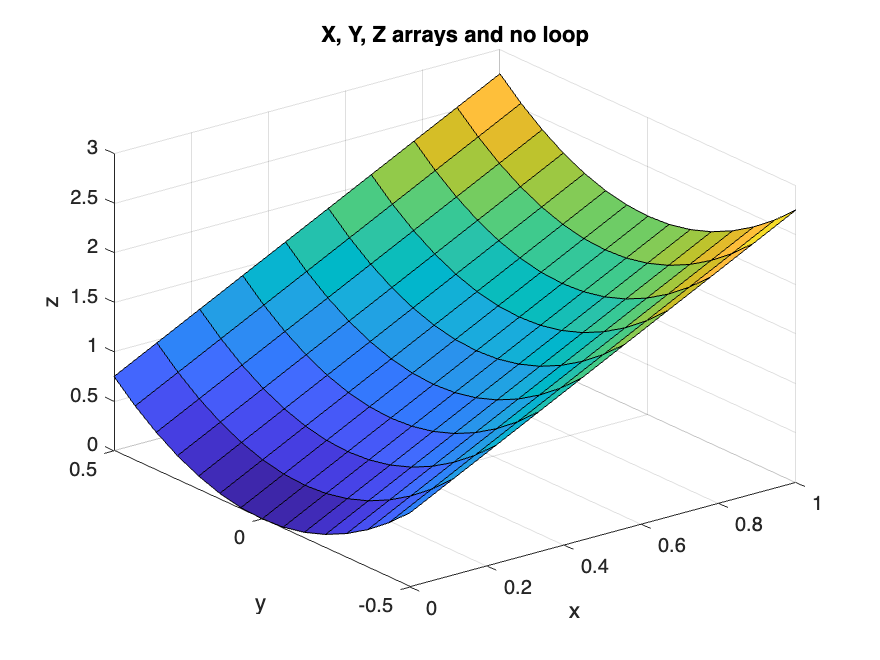

noloopT = tic;
x = linspace(0,1,10); % make uniform array of size 10 on [0,1]
y = linspace(-0.5,0.5,15); % make uniform array of size 15 on [-0.5,0.5]
[X,Y] = meshgrid(x,y); % create meshgrid of x and y values

z = m1*X + m2*Y.^2; % calculate z using X and Y

noloopT = toc(noloopT);
figure(3); clf
surf(x,y,z);
xlabel('x');
ylabel('y');
zlabel('z');
title('X, Y, Z arrays and no loop');

disp("Run Time for X, Y, Z arrays and no loop");

Run Time for X, Y, Z arrays and no loop


disp(noloopT);

    0.0064



**(3 points) **Finally, define an anonymous function f(x,y) to compute z as defined above, and use the built-in function` fsurf `to plot this function on the domain [0,1]x[-0.5,0.5]. How does this plot compare to your plots above? (Please write your discussion in the string in the following block.)

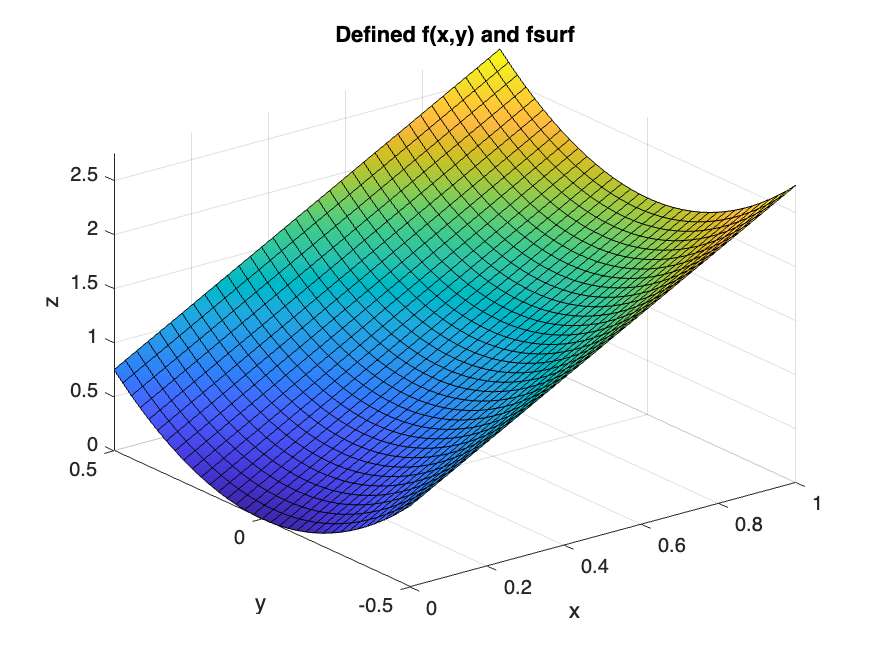

f = @(x,y) m1*x + m2*y.^2; % function to compute z

figure(4); clf
fsurf(f,[0 1 -0.5 0.5]);  % fsurf with proper domain
xlabel('x');
ylabel('y');
zlabel('z');
title('Defined f(x,y) and fsurf');


disp(['This plot is extremely similar to the plots above, where it has the same shape and heat map.  ' ...
    'However, there are clearly many more datapoints of x and y considered.  ' ...
    'Thus, we have a smoother plot.'])

This plot is extremely similar to the plots above, where it has the same shape and heat map.  However, there are clearly many more datapoints of x and y considered.  Thus, we have a smoother plot.
